# Performing the discrete Fourier transform on a data set

In this MATLAB live script, we have a discrete sample data set that we analyse using the discrete Fourier transform (in particular, a procedure called the "Fast Fourier Transform") in order to determine what the important underlying frequencies are.

clear

## 1. Importing the raw data

First, we need to import our two sets of data from the EXCEL spreadsheet  "DiscreteFourierMatlabData.xlsx" where they are found in two columns with one header row containing the names of the columns:

The sampling times are contained in vector* t*, and the sampled values of the function at those times are in vector *f*.

This can be done as in the Tutorial 11 Q1 walkthrough by manually clicking, *or* it can be automated using the "importdata" command that we demonstrate here:

data_set = importdata('DiscreteFourierMatlabData.xlsx','',1)

data_set = struct with fields:
          data: [256×2 double]
      textdata: {'Time [s]'  'Amplitude [mm]'}
    colheaders: {'Time [s]'  'Amplitude [mm]'}


The importdata() command has three arguments:

- First the name of the file. This must be located in the same folder MATLAB is working from.

- Second, ' ' tells MATLAB that data are separated by spaces in EXCEL.

- Third, 1 in the final argument is the number of "header rows" containing the column titles.


t = data_set.data(:,1) % the first column is t

t =          0
    0.0392
    0.0784
    0.1176
    0.1569
    0.1961
    0.2353
    0.2745
    0.3137
    0.3529


f = data_set.data(:,2) % the second column is f

f =          0
    0.3199
    0.5719
    0.7263
    0.8033
    0.8511
    0.9062
    0.9638
    0.9787
    0.8976


There are 256 examples, which is a power of 2. This is necessary for technical purposes.

## 2. Visualise the raw data on a scatter plot

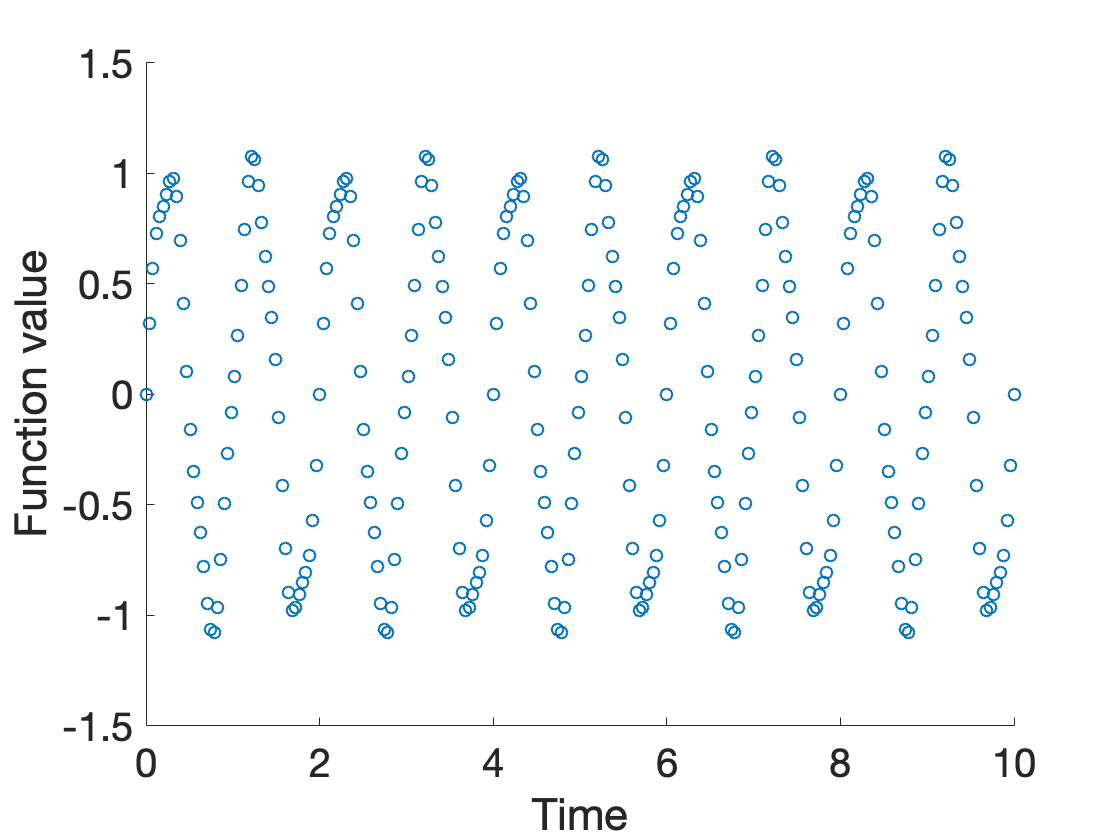

scatter(t,f)
xlabel('Time')
ylabel('Function value')

## 3. Taking the Fourier Transform

The next thing to do is to take the discrete Fourier transform of our sampled data.

To do this, use the Fast Fourier Transform algorithm:

F = fft(f);

This gives us a set of 256** complex numbers**.

However, we only want the **magnitudes** (related to the one-sided power spectral density). These can be obtained using the absolute value command:

m = abs(F)

m =     0.0000
    0.1028
    0.2118
    0.3346
    0.4822
    0.6730
    0.9424
    1.3713
    2.1983
    4.5784


This is the *y*-axis data that we want for our plot. But what about the *x*-axis?

To draw the frequency spectrum, we need *x*-axis values of the actual frequencies to which these magnitudes correspond.

First, we need to know the frequency spacing (*s*). This is simply the reciprocal of the duration (*T*=10) of the sample. 

s=1/10

s = 0.1000

Recall from the lecture that there should be *(N/2)-1* values of the frequency.

In this example, that means we want 127 values, that start at 0 and increase by the frequency spacing of *s*=0.1. There are many ways of iterating in MATLAB to create this vector, but one way is:

xStart = 0

xStart = 0

N=256

N = 256

num=N/2-1 % this is 127

num = 127

x = xStart + (0:num-1)*s % this generates our evenly-spaced vector

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


## 4. Plotting the Frequency  Sprectrum

Finally, we want to plot the frequency spectrum, but we will only need the first *(N/2)-1* magnitude values.

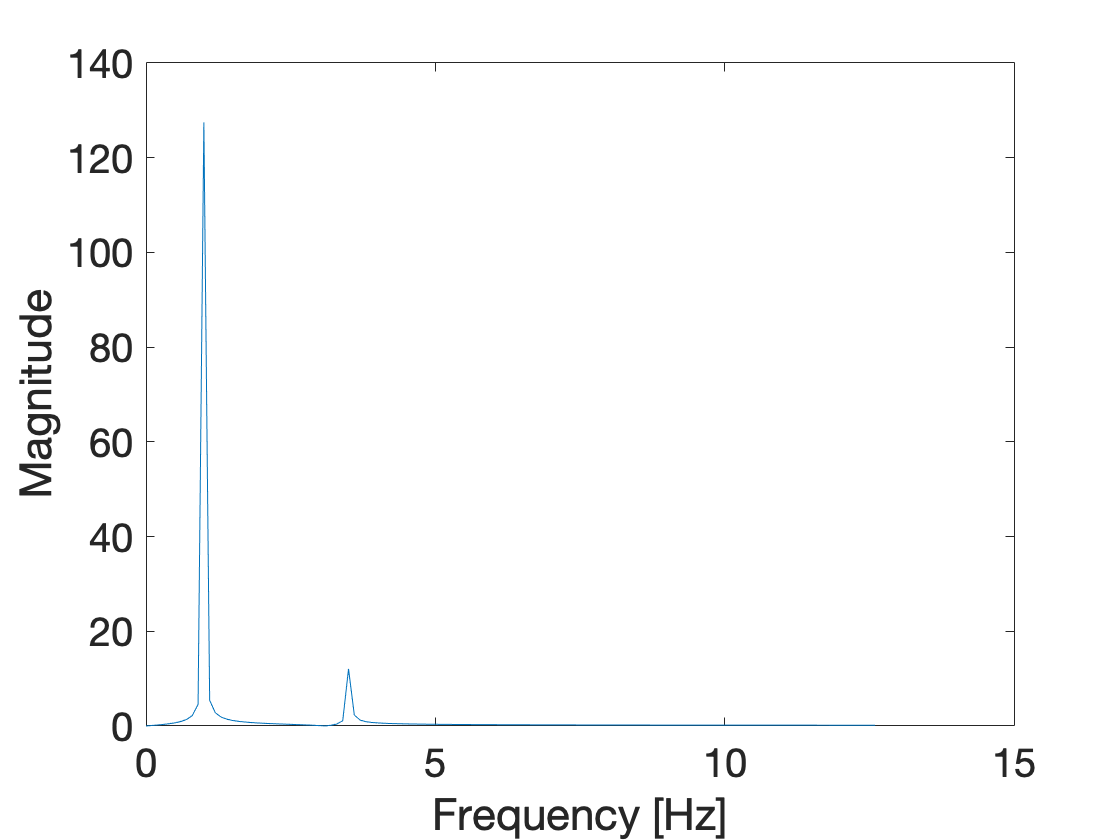

plot(x,m(1:num))
xlabel('Frequency [Hz]')
ylabel('Magnitude')

As we can see, there are two main peaks:

- A frequency about 1 Hz that is relatively dominant.

- And a another lesser frequency at about 3.5 Hz.

So the signa being sampled here is probably the combination of two sine waves, with the lower frequency one being much more powerful.

Let's see if that really is the case!

## 5. Reconstructing the waveform

This signal consists of two sine wave:

- The first has frequency of 1 Hz and hence angular frequency of 2 pi. It has a magnitude in the frequency domain of 127.5 

- The second has frequency 3.5 Hz and thus an angular frequency of 7 pi. It has a magnitude 12.06

From inspecting the original scatter plot very closely, we can measure that over a single 1 second oscillation it has amplitude 1.0278. We will use this information to *scale* our sine waves to match the data: the largest one (which controls the 1 Hz oscillation that we can see from the time series) should have this amplitude, while the other should have an amplitude equal to 12.06/127.5 times this.

Hence we can reconstruct the function of time as:

f_wave = (1.0278/127.5) * (127.5*sin(2*pi*t) + 12.06*sin(7*pi*t))

f_wave =          0
    0.3245
    0.5823
    0.7436
    0.8273
    0.8798
    0.9364
    0.9919
    1.0027
    0.9170


Let's plot this curve on the same axes as the data sample:

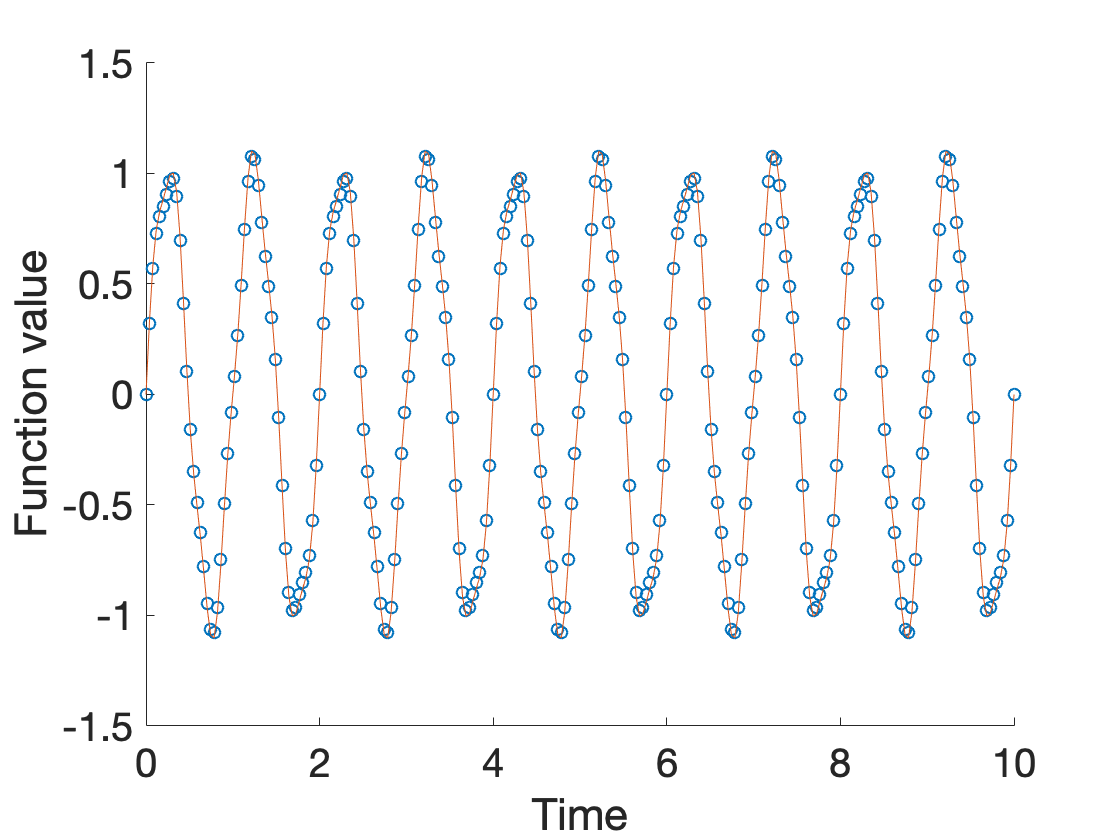

scatter(t,f)
xlabel('Time')
ylabel('Function value')

hold on
plot(t,f_wave)

We can see that this appears to perfectly match the data observed!

Depending on the kind of data this represents, you could then manipulate the signal in different ways - boosting desired frequencies (e.g. human speech in the audio transmission of a phone call) or removing undesirable ones (e.g. those outside of human hearing range to reduce music file sizes).